l = 19.75;
lambda = 532e-9;
m = 1;

x = 7.45;

angle = atan(x/l);
d = lambda / sin(angle) * 1e6

d = 1.5073

x = 6.5

x = 6.5000

angle = atan(x/l)

angle = 0.3179

lambda = sin(angle) * d

lambda = 0.4712

data = readtable("dark.txt");

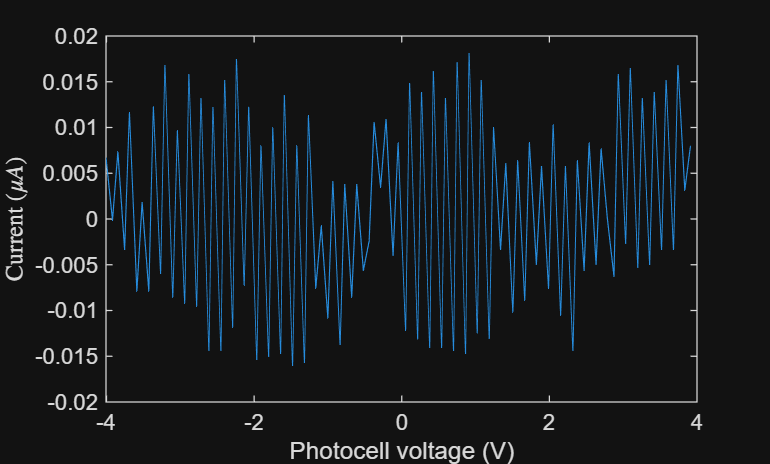

intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);
xlabel("Photocell voltage (V)");
ylabel("Current (\(\mu A)\)", "Interpreter","latex");


difference = diff(intensity);
noise = mean(difference)*1e6

noise = 13.2644

figure;
hold on;
data = readtable("blue.txt");

intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity, "Color","blue");

constSlope = 3.3641e-05

constIntercept = -0.0180


data = readtable("uv.txt");

intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity, "Color","#8F00FF");

data = readtable("green.txt");

intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity, "Color","green");

data = readtable("yellow.txt");

intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity, "Color","yellow");

data = readtable("red.txt");

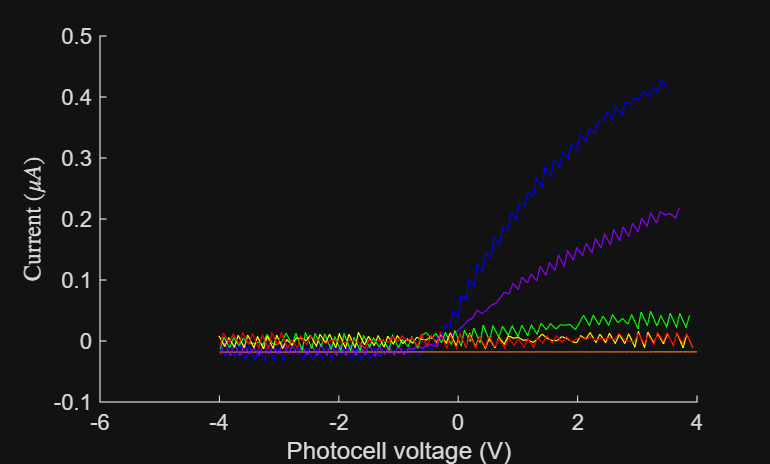

intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity, "Color","red");

xlabel("Photocell voltage (V)");
ylabel("Current (\(\mu A)\)", "Interpreter","latex");

figure;
data = readtable("green_wide.txt");

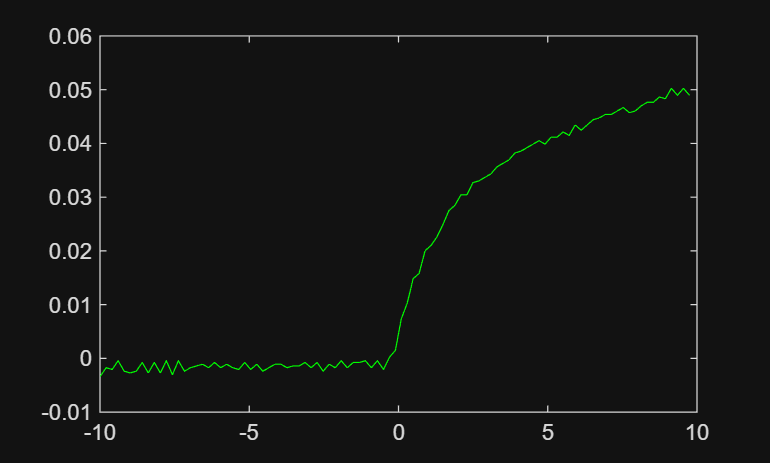

intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity, "Color","green");

figure;
hold on;
data = readtable("uv.txt");

intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);

constantIntensity = intensity(position < -.5);
constantPosition = position(position < -.5);
constFit = polyfit(constantPosition,constantIntensity,1);
constSlope = constFit(1)

constSlope = 5.3375e-04

constIntercept = constFit(2)

constIntercept = -0.0133

x = linspace(-4,4,100);
plot(x,constIntercept + x * constSlope);

linIntensity = intensity(position > 0 & position < 1);
linPosition = position(position > 0 & position < 1);
linFit = polyfit(linPosition, linIntensity, 1);
linSlope = linFit(1)

linSlope = 0.0746

linIntercept = linFit(2)

linIntercept = 0.0190

plot(x, linIntercept + linSlope * x);

Uth = (constIntercept - linIntercept) / (linSlope - constSlope)

Uth = -0.4363

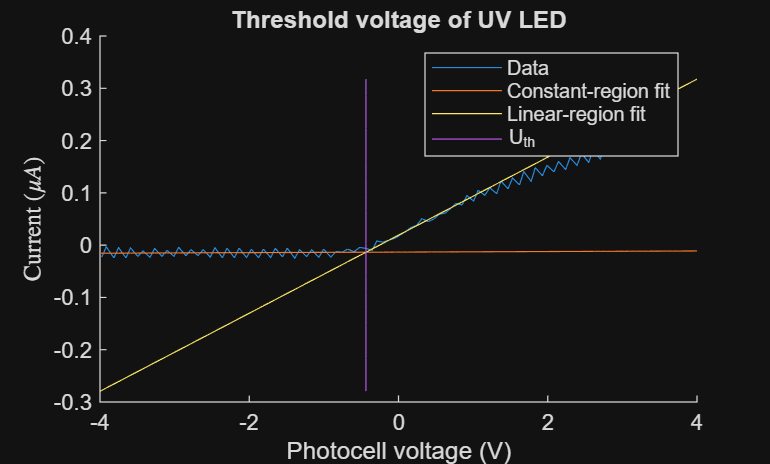

Ith = linIntercept + linSlope*Uth;
plot(linspace(Uth,Uth,20),linspace(linIntercept + -4*linSlope, linIntercept + 4*linSlope,20))

xlabel("Photocell voltage (V)");
ylabel("Current (\(\mu A)\)", "Interpreter","latex");
legend("Data", "Constant-region fit", "Linear-region fit","U_{th}");
title("Threshold voltage of UV LED")

figure;
hold on;
data = readtable("blue.txt");

intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);

constantIntensity = intensity(position < -.5);
constantPosition = position(position < -.5);
constFit = polyfit(constantPosition,constantIntensity,1);
constSlope = constFit(1)

constSlope = 3.3641e-05

constIntercept = constFit(2)

constIntercept = -0.0180

x = linspace(-4,4,100);
plot(x,constIntercept + x * constSlope);

linIntensity = intensity(position > 0 & position < 1);
linPosition = position(position > 0 & position < 1);
linFit = polyfit(linPosition, linIntensity, 1);
linSlope = linFit(1)

linSlope = 0.1608

linIntercept = linFit(2)

linIntercept = 0.0572

plot(x, linIntercept + linSlope * x);

Uth = (constIntercept - linIntercept) / (linSlope - constSlope)

Uth = -0.4674

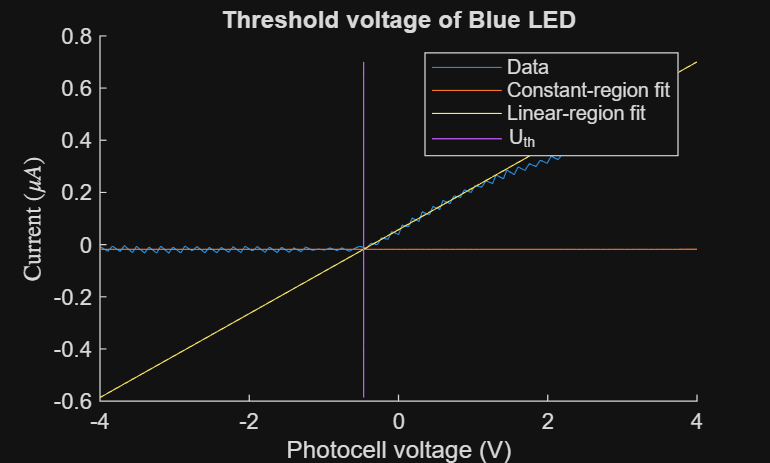

Ith = linIntercept + linSlope*Uth;
plot(linspace(Uth,Uth,20),linspace(linIntercept + -4*linSlope, linIntercept + 4*linSlope,20))

xlabel("Photocell voltage (V)");
ylabel("Current (\(\mu A)\)", "Interpreter","latex");
legend("Data", "Constant-region fit", "Linear-region fit","U_{th}");
title("Threshold voltage of Blue LED")

figure;
hold on;
data = readtable("green.txt");

intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);

constantIntensity = intensity(position < -.5);
constantPosition = position(position < -.5);
constFit = polyfit(constantPosition,constantIntensity,1);
constSlope = constFit(1)

constSlope = 4.3016e-04

constIntercept = constFit(2)

constIntercept = -3.2807e-04

x = linspace(-4,4,100);
plot(x,constIntercept + x * constSlope);

linIntensity = intensity(position > 0 & position < 1);
linPosition = position(position > 0 & position < 1);
linFit = polyfit(linPosition, linIntensity, 1);
linSlope = linFit(1)

linSlope = 0.0184

linIntercept = linFit(2)

linIntercept = 0.0030

plot(x, linIntercept + linSlope * x);

Uth = (constIntercept - linIntercept) / (linSlope - constSlope)

Uth = -0.1873

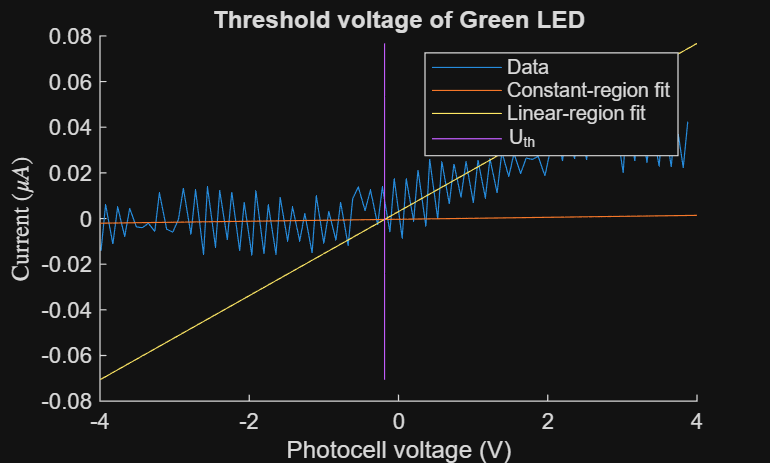

Ith = linIntercept + linSlope*Uth;
plot(linspace(Uth,Uth,20),linspace(linIntercept + -4*linSlope, linIntercept + 4*linSlope,20))

xlabel("Photocell voltage (V)");
ylabel("Current (\(\mu A)\)", "Interpreter","latex");
legend("Data", "Constant-region fit", "Linear-region fit","U_{th}");
title("Threshold voltage of Green LED")

figure;
hold on;
data = readtable("yellow_wide.txt");

intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);

constantIntensity = intensity(position < -.5);
constantPosition = position(position < -.5);
constFit = polyfit(constantPosition,constantIntensity,1);
constSlope = constFit(1)

constSlope = -2.8366e-05

constIntercept = constFit(2)

constIntercept = 5.0413e-04

x = linspace(-10,10,100);
plot(x,constIntercept + x * constSlope);

linIntensity = intensity(position > 0 & position < 5);
linPosition = position(position > 0 & position < 5);
linFit = polyfit(linPosition, linIntensity, 1);
linSlope = linFit(1)

linSlope = 1.8787e-04

linIntercept = linFit(2)

linIntercept = 9.2184e-04

plot(x, linIntercept + linSlope * x);

Uth = (constIntercept - linIntercept) / (linSlope - constSlope)

Uth = -1.9318

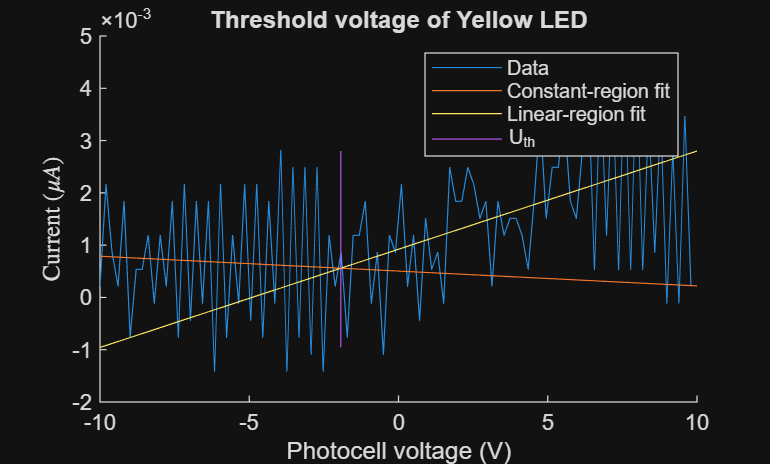

Ith = linIntercept + linSlope*Uth;
plot(linspace(Uth,Uth,20),linspace(linIntercept + -10*linSlope, linIntercept + 10*linSlope,20))

xlabel("Photocell voltage (V)");
ylabel("Current (\(\mu A)\)", "Interpreter","latex");
legend("Data", "Constant-region fit", "Linear-region fit","U_{th}");
title("Threshold voltage of Yellow LED")

figure;
hold on;
data = readtable("red_wide.txt");

intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);

constantIntensity = intensity(position < -2);
constantPosition = position(position < -2);
constFit = polyfit(constantPosition,constantIntensity,1);
constSlope = constFit(1)

constSlope = 3.3626e-05

constIntercept = constFit(2)

constIntercept = 7.9064e-04

x = linspace(-10,10,100);
plot(x,constIntercept + x * constSlope);

linIntensity = intensity(position > 1 & position < 7);
linPosition = position(position > 1 & position < 7);
linFit = polyfit(linPosition, linIntensity, 1);
linSlope = linFit(1)

linSlope = 1.6809e-04

linIntercept = linFit(2)

linIntercept = 8.7737e-04

plot(x, linIntercept + linSlope * x);

Uth = (constIntercept - linIntercept) / (linSlope - constSlope)

Uth = -0.6450

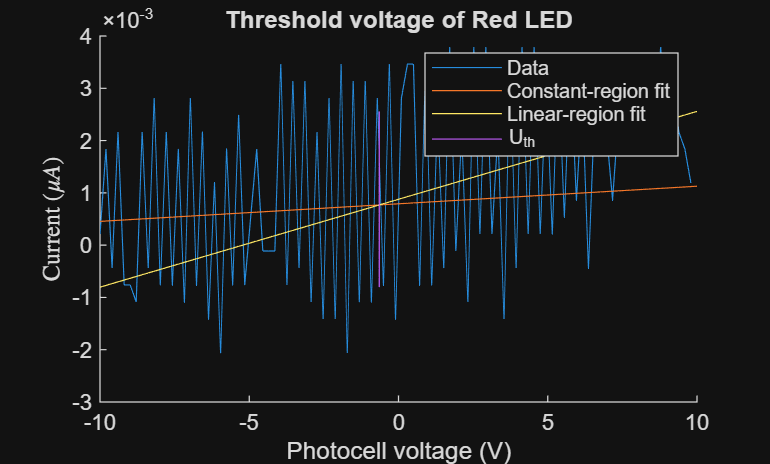

Ith = linIntercept + linSlope*Uth;
plot(linspace(Uth,Uth,20),linspace(linIntercept + -10*linSlope, linIntercept + 10*linSlope,20))

xlabel("Photocell voltage (V)");
ylabel("Current (\(\mu A)\)", "Interpreter","latex");
legend("Data", "Constant-region fit", "Linear-region fit","U_{th}");
title("Threshold voltage of Red LED")